# **Taller filtros adatpativos**

y(n)=L+v(n)

- v(n): error, ruido

- L: señal ideal constante

- y(n):señal a muestrear

Estimación de la media


$$\hat{L} \left(N\right)=\sum_{k=1}^N \frac{1}{N}y\left(k\right)$$


Se modifica el anterir, para obtener una estimación con un valor actual  y un valor anterior. Estimador no muy bueno pero sencillo.


$$\hat{L} \left(N\right)=\frac{y\left(N\right)+\left(N-1\right)\widehat{L} \left(N-1\right)}{N}$$


**Filtro Wiener**


$$y\left(n\right)=x\left(n\right)+v\left(n\right)$$


- y(n):señal a muestrar

- x(n): señal ideal variable

- v(n): ruido

Función de error


$$e\left(n\right)=x\left(n\right)-\hat{x} \left(n\right)$$


- $\hat{x} \left(n\right)$: estimador

- x(n): señal ideal variable

- $e\left(n\right)$: error en una muestra

Error cuadrático medio, error general, esperanza del error 


$$\mathrm{MSE}=E\left(e^2 \right)$$


Definición del estimador $\hat{x} \left(n\right)$, convolución, filtro FIR, no causal


$$\hat{x} \left(n\right)=\sum_{k=-\infty }^{\infty } h\left(k\right)y\left(n-k\right)$$


- h(k): respuesta al impulso


$$\mathrm{MSE}=E\left({\left(\sum_{k=-\infty }^{\infty } h\left(k\right)y\left(n-k\right)-x\left(n\right)\right)}^2 \right)$$


Minimizar el error con la derivada, el resultado se basa en el principio de ortogonalidad, donde el producto punto es cero, también se podría ver como la correlación cruzada(La correlacción entre la señal esperada y la señal de entrada es la misma que la correlación entre la señal estimada y la señal de entrada).


$$\frac{d\left(\mathrm{MSE}\right)}{\mathrm{dh}\left(m\right)}=E\left(\left.2\left(\sum_{k=-\infty }^{\infty } h\left(k\right)y\left(n-k\right)-x\left(n\right)\right)y-m\right)\right)=0$$



$$E\left(e\left(n\right)y\left(n-m\right)\right)=R_{\mathrm{ey}} \left(m\right)=E\left(\left(x\left(n\right)-\hat{x} \left(n\right)\right)y\left(n-m\right)\right)=R_{\mathrm{xy}} \left(m\right)-R_{\hat{\mathrm{x}} y} \left(m\right)=0$$



$$R_{\mathrm{xy}} \left(m\right)=R_{\hat{\mathrm{x}} y} \left(m\right)=\sum_{k=-\infty }^{\infty } h\left(k\right)R_{\mathrm{yy}} \left(m-k\right)$$


Transformada Z a lo anterior


$$H\left(z\right)=\frac{S_{\mathrm{xy}} \left(z\right)}{S_{\mathrm{yy}} \left(z\right)}$$


La señal y el ruido no deben estar corelacionadas


$$R_{\mathrm{xv}} \left(n,m\right)=E\left(x\left(n\right)v\left(n\right)\right)=0$$



$$R_{\mathrm{yy}} \left(n,m\right)=E\left(y\left(n\right)y\left(m\right)\right)=\left(n,m\right)=E\left(\left(x\left(n\right)+v\left(n\right)\right)\left(x\left(m\right)+v\left(m\right)\right)\right)=R_{\mathrm{xx}} \left(n,m\right)+R_{\mathrm{vv}} \left(n,m\right)$$



$$R_{\mathrm{xy}} \left(n,m\right)=E\left(x\left(n\right)y\left(m\right)\right)=E\left(x\left(n\right)\left(x\left(n\right)+v\left(n\right)\right)\right)=R_{\mathrm{xx}} \left(n,m\right)$$



$$H\left(z\right)=\frac{S_{\mathrm{xx}} \left(z\right)}{S_{\mathrm{xx}} \left(z\right)+S_{\mathrm{vv}} \left(z\right)}$$


%Clear environment
clc 
clear all
close all

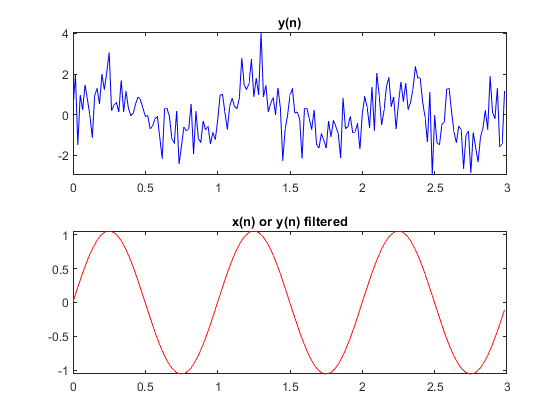

%Filtro Wiener
f=1;
w=2*pi*f;
fs=60;
Ts=1/fs;
t=0:Ts:(3-Ts);%3 periodos
x=sin(w*t);%señal esperada
Nx=length(x);
v=randn(1,Nx);%señal de ruido
y=x+v; %señal de salida

x_fft=fft(x); %FFt de x
Sxx=abs(x_fft).^2;%Autocorrelación de x
v_fft=fft(v);%FFT de v
Svv=abs(v_fft).^2;%Autocorrelación de v
H=Sxx./(Sxx+Svv); %Filtro
y_fft=fft(y);%FFT de y
y_filtered=real(ifft(y_fft.*H));
%Plots
figure(1)
subplot(2,1,1)
plot(t,y,'b'); %señal de salida
title('y(n)');
subplot(2,1,2)
plot(t,y_filtered,'r');%señal de salida filtrada
title('x(n) or y(n) filtered');

Si el estimador es finito


$$\hat{x} \left(n\right)=\sum_{k=a}^b h\left(k\right)y\left(n-k\right)$$


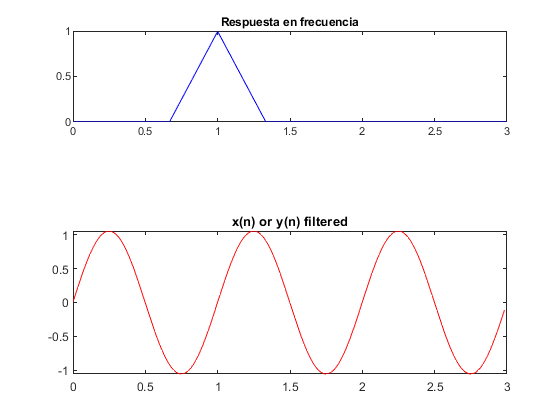

%Filtro de una dimensión
h=real(ifft(H));
y_filtered2=filter(h,1,y);
%Plots
figure(1)
subplot(3,1,1)
f_i=fs/Nx;
f_interval=0:f_i:3;
plot(f_interval,H(1:length(f_interval)),'b'); %Respuesta en frecuencia
title('Respuesta en frecuencia');

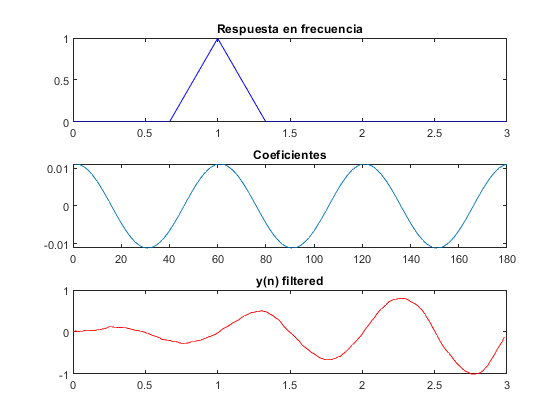

subplot(3,1,2)
plot(h)
title("Coeficientes")
subplot(3,1,3)
plot(t,y_filtered2,'r');%señal filtrada
title('y(n) filtered');

Si el estimador es finito


$$\hat{x} \left(n\right)=\sum_{k=0}^{N-1} h\left(k\right)y\left(n-k\right)$$



$$R_{\mathrm{xy}} \left(m\right)=\sum_{k=-\infty }^{\infty } h\left(k\right)R_{\mathrm{yy}} \left(m-k\right)$$



$$R_y h=r_{\mathrm{xy}}$$



$$h=r_{\mathrm{xy}} {R_y }^{-1}$$


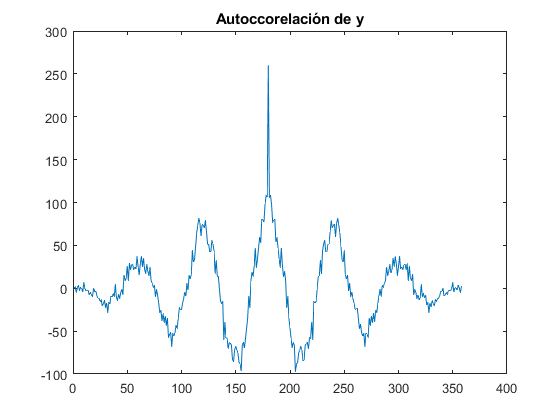

%Autocorrelación y correlación cruzada
syy=xcorr(y);
sxy=xcorr(x,y);
figure(3);
plot(syy);
title("Autoccorelación de y");

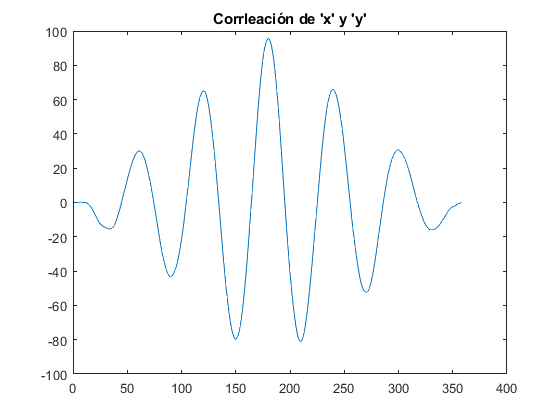

plot(sxy)
title("Corrleación de 'x' y 'y'");

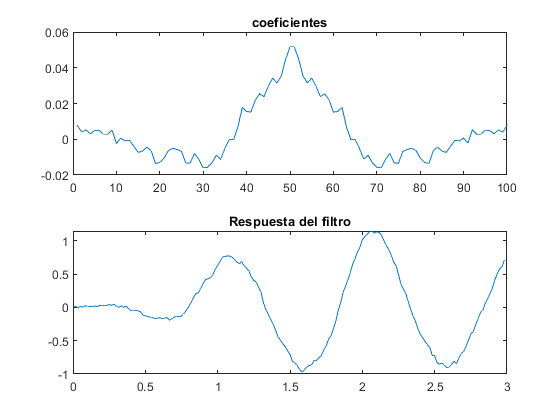

%El objetivo es obtener coeficientes simétricos en el filtro
Nh=50; %Número finitos de muestras
Ry=toeplitz(syy(Nx:Nx+Nh-1));%Ry es matriz tipo toeplitz
rxy=sxy(Nx:Nx+Nh-1);
h=Ry\rxy';
rh=h';
lh=fliplr(rh);
hh=0.5*[lh rh];
y_filtered=filter(hh,1,y);

%Analizar simetría del filtro
figure(4)
subplot(2,1,1)
plot(hh);
title("coeficientes")
subplot(2,1,2)
plot(t,y_filtered)
title("Respuesta del filtro")

**RLS**


$$h=r_{\mathrm{xy}} {R_y }^{-1}$$



$$R_y \left(n\right)=\sum_{k=1}^n y\left(k\right)y^T \left(k\right)=\sum_{k=1}^{n+1} y\left(k\right)y^T \left(k\right)+y\left(n\right)y^T \left(n\right)=R_y \left(n-1\right)++y\left(n\right)y^T \left(n\right)$$



$$r_{\mathrm{xy}} \left(n\right)=r_{\mathrm{xy}} \left(n-1\right)+x\left(n\right)y\left(n\right)$$


identidad de Woodley


$$A=B^{-1} +CD^{-1} C^T$$



$$A^{-1} =B+\mathrm{BC}{\left(D+C^T \mathrm{BC}\right)}^{-1} C^T B$$



$$A=R_y \left(n\right)$$



$$B=R_y^{-1} \left(n-1\right)$$



$$C=y\left(n\right)$$



$$D=1$$



$${{L\left(n\right)=R}_y }^{-1} \left(n\right)={R_y }^{-1} \left(n-1\right)-\frac{{R_y }^{-1} \left(n-1\right)y\left(n\right)y^T \left(n\right){R_y }^{-1} \left(n-1\right)}{1+y^T \left(n\right){R_y }^{-1} \left(n-1\right)y\left(n\right)}$$



$$K\left(n\right)=\frac{{R_y }^{-1} \left(n-1\right)y\left(n\right)}{1+y^T {R_y }^{-1} \left(n-1\right)y\left(n\right)}$$



$$L\left(n\right)=L\left(n-1\right)+K\left(n\right)y^T \left(n\right)L\left(n-1\right)$$



$$K\left(n\right)=\left\lbrack L\left(n-1\right)-K\left(n\right)y^T \left(n\right)L\left(n-1\right)\right\rbrack y\left(n\right)=L\left(n\right)y\left(n\right)$$



$$h\left(n\right)={R_y }^{-1} \left(n\right)r_{\mathrm{xy}} \left(n\right)=L\left(n\right)\left\lbrack r_{\mathrm{xy}} \left(n-1\right)+x\left(n\right)y\left(n\right)\right\rbrack =\left\lbrack L\left(n-1\right)+K\left(n\right)y^T \left(n\right)L\left(n-1\right)r_{\mathrm{xy}} \left(n-1\right)\right\rbrack +K\left(n\right)x\left(n\right)$$



$$h\left(n-1\right)=L\left(n-1\right)r_{\mathrm{xy}} \left(n-1\right)=h\left(n-1\right)+K\left(n\right)\left\lbrack x\left(n\right)-y^T \left(n\right)h\left(n-1\right)\right\rbrack$$



$$h\left(n\right)=h\left(n-1\right)+K\left(n\right)e\left(n\right)$$


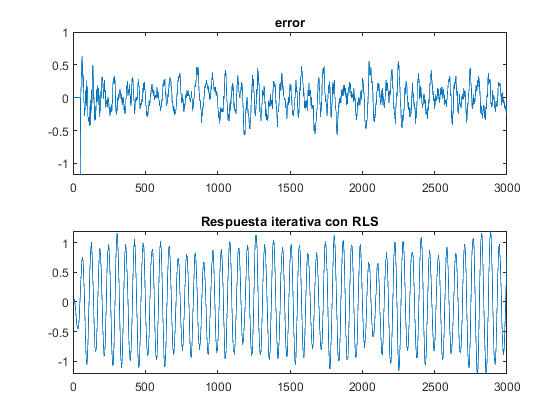

%RLS
f=1;
w=2*pi*f;
fs=60;
Ts=1/fs;
t=0:Ts:(50-Ts);%3 periodos
x=sin(w*t);%señal esperada
Nx=length(x);
v=randn(1,Nx);%señal de ruido
y=x+v; %señal de salida
Nh=50; %número de coeficientes 
h=ones(Nh,1)/Nh;
yy=zeros(Nh,1);
err=zeros(1,Nx);
y_filtered=zeros(1,Nx);
L=eye(Nh);
K=zeros(Nh,1);
for nn=Nh:Nx-1
    yy=y(nn:-1:(nn-Nh+1))';
    K=L*yy/(1+yy'*L*yy);
    y_filtered=h'*yy;
    err(nn)=x(nn)-y_filtered;
    h=h+K*err(nn);
    L=L-(K*yy')*L;
end

rh=h';
lh=fliplr(rh);
hh=0.5*[lh rh];
y_filtered=filter(hh,1,y);
figure
subplot(2,1,1)
plot(err)
title("error")
subplot(2,1,2)
plot(y_filtered);
title("Respuesta iterativa con RLS")

LMS

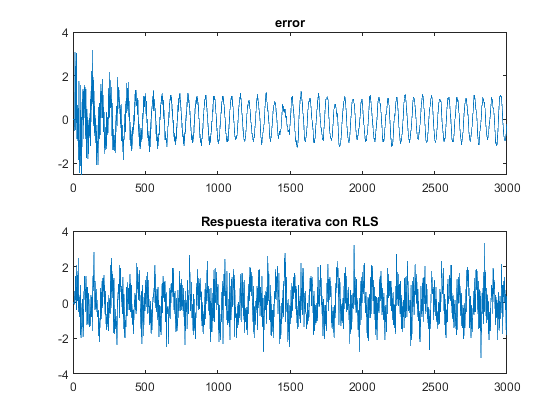

%LMS
f=1;
w=2*pi*f;
fs=60;
Ts=1/fs;
t=0:Ts:(50-Ts);%3 periodos
x=sin(w*t);%señal esperada
Nx=length(x);
v=randn(1,Nx);%señal de ruido
y=x+v; %señal de salida
Nh=12; %número de coeficientes 

lr=0.01; %learning rate

h=zeros(Nh,1);
vv=zeros(Nh,1);
err=zeros(Nh,1);
y_filtered=zeros(Nh,1);
mu=0.1;
for nn=Nh:Nx-1
    vv=v(nn:-1:(nn-Nh+1))';
    y_filtered(nn)=h'*vv;
    err(nn)=y(nn)-y_filtered(nn);
    aux=lr/(mu+norm(vv));
    h=h+(aux*err(nn)*vv);
end

rh=h';
lh=fliplr(rh);
hh=0.5*[lh rh];
y_filtered=filter(hh,1,y);
figure
subplot(2,1,1)
plot(err)
title("error")
subplot(2,1,2)
plot(y_filtered);
title("Respuesta iterativa con LMS")